# 802.11n Minstrel-HT Rate Control Algorithm

This example shows Minstrel-HT rate control by varying the Modulation and Coding scheme (MCS) of successive packets transmitted over a frequency selective multipath fading channel.

## Introduction

The IEEE® 802.11™ standard supports Minstrel-HT rate control by adjusting the MCS value of each transmitted packet based on the underlying radio propagation channel. Maximizing link throughput, in a propagation channel that is time varying due to multipath fading or movement of the surrounding objects, requires dynamic variation of MCS. The IEEE 802.11 standard does not define any standardized rate control algorithm (RCA) for dynamically varying the modulation rate. The implementation of RCA is left open to the WLAN device manufacturers. This example uses a open-loop rate control scheme. The algorithm is based on MinstrelHtWifimanager from NS3. Minstrel-HT is a rate adaptation mechanism for the 802.11n/ac/ax standards based on Minstrel-nonHT, and is based on the approach of probing the channel to dynamically learn about working rates that can be supported. Minstrel-HT is designed for high-latency devices that implement a Multiple Rate Retry (MRR) chain. This kind of device does not give feedback for every frame retransmission, but only when a frame was correctly transmitted (an Ack is received) or a frame transmission completely fails (all retransmission attempts fail). The MRR chain is used to advise the hardware about which rate to use when retransmitting a frame.

## The Minstrel-HT Algorithm

Minstrel-HT algorithms specifically used in 802.11n it adapts the data rate based on the statistical table of the results of the *Sampling period* and *Non-Sampling period*. Minstrel-HT is made for the use of data rate based on 20/40 MHz bandwidth, LGI/SGI and the number of spatial streams can be adapted to channel conditions. The number of group rate is determined by the number of spatial streams, the duration of the GI and the size of the bandwidth used.

#### Initialize all HT Groups

Minstrel-HT begins with the initialization of the HT data rate group. Initialization HT data rate group performed to identify the data rate group is supported by transmitter and is based on the number of streams, GI and bandwidth. For each group, a flag indicates if the group is supported by the station. Different stations communicating with an AP can have different capabilities. In the example below the station only supports 1 spatial stream, Long GI and a Bandwidth of 20MHz, the group is named as Group-[1,L,20].

#### Initialize Sample Table

Then Initializing of Sample Table for the initiation of sampling rate is created based on the generation of uniform random number generator.

#### MRR table update

MRR table update is repeated within a period of 50 ms. In each MRR table update, throughput and EWMA is updated for each rate in each group. Throughput is calculated with the following provisions:

                  If the EWMA probability < 10 then the throughput assumed to be zero. If the EWMA probability > 90 then the throughput is calculated based on the equation (throughput = 90/txTime). For EWMA probability 10 ≤ ewmaProb ≤ 90 then throughput = ewmaProb/txTime. ewmaProb and throughput is calculated for all the sampling rates and MRR updates at this period. 

Then the algorithm determines the new max_tp, max_tp2 and max_prob creatibng a table. The new max_tp is the rate that has the highest throughput. The New max_tp2 is who has the second highest throughput. The new max_prob is a sample rate that has the highest EWMA probability. 

#### Non-Sampling Period

These rates are only used when an entire packet fails and is retried(C1,C2 and C3 times respectively) in *Non-Sampling Period*.

#### Sampling period 

In *Sampling period*, the Sampling rate that results in the highest throughput and highest probability of successful delivery of the packet and also not part of the MRR table is used as the data rate for the next packet delivery, sampling is done on all the existing rate in each group rate. The detailed flowchart of the algorithm is attached as PDF, this figure briefly explains the Minstrel-HT.

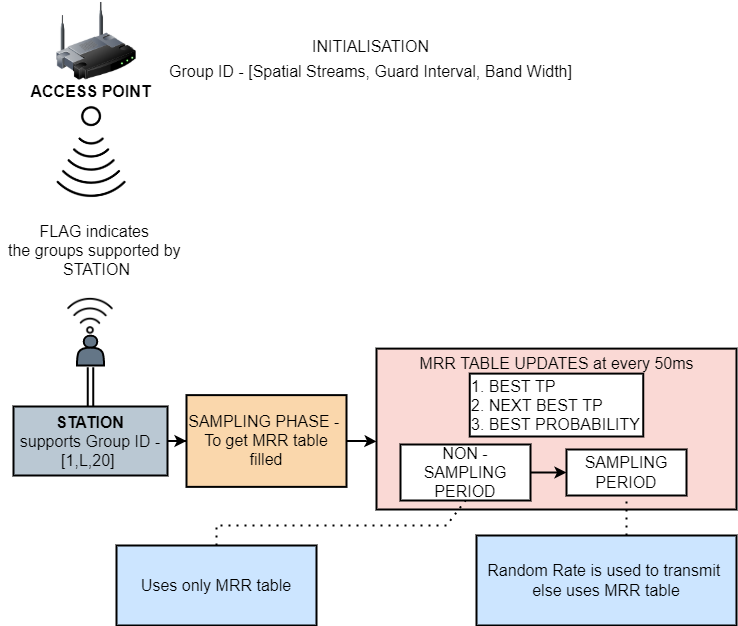

## Matlab Implementation

In this example, an 802.11n HT waveform consisting of a single HT format packet is generated using the [`wlanWaveformGenerator`](https://in.mathworks.com/help/wlan/ref/wlanwaveformgenerator.html) function. The waveform is passed through a TGn channel and noise is added. The packet is synchronized and decoded to recover the PSDU. Then Frame Success Ratio(FSR) is calculated and based on FSR the algorithm fills the MRR table during the Sampling phase and later enters into alternate *Non-Sampling period* and *Sampling period*. This figure shows the processing for each packet.

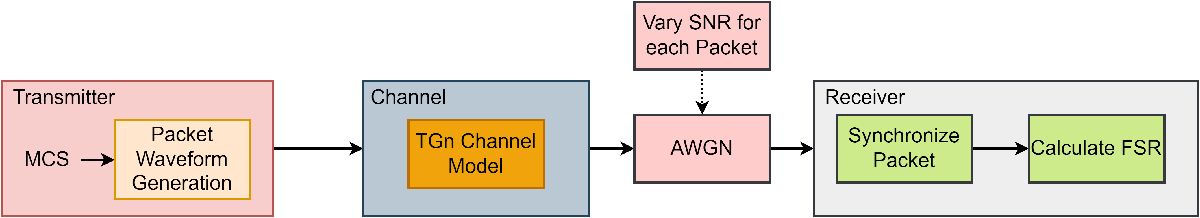

## Waveform Configuration

An IEEE 802.11n HT transmission is simulated in this example. The HT waveform properties are specified in a [`wlanHTConfig`](https://in.mathworks.com/help/wlan/ref/wlanhtconfig.html) configuration object. In this example the object is initially configured for a 20 MHz channel bandwidth, single transmit antenna and long guard interval. The MCS for the subsequent packets is changed by the algorithm throughout the simulation.

cfgHT = wlanHTConfig;             % Create wlanHTConfig object
cfgHT.ChannelBandwidth = 'CBW20'; % Channel bandwidth in MHz(CBW40 for 40MHz)
cfgHT.NumTransmitAntennas = 1;    % Transmit antennas
cfgHT.NumSpaceTimeStreams = 1;    % Spatial Streams
cfgHT.GuardInterval = 'Long';     % Gaurd Interval
cfgHT.PSDULength = 4096;          % PSDU length in bytes

## Channel Configuration

In this example a TGn N-LOS channel model is used with delay profile Model-D. For Model-D when the distance between the transmitter and receiver is greater than or equal to 10 meters, the model is NLOS. This is described further in [wlanTGnChannel](docid:wlan_ref#buy2ffw-1).

tgnChannel = wlanTGnChannel;
tgnChannel.DelayProfile = 'Model-D';
tgnChannel.NumTransmitAntennas = 1;
tgnChannel.NumReceiveAntennas = 1;
tgnChannel.TransmitReceiveDistance = 20; % Distance in meters for NLOS
tgnChannel.LargeScaleFadingEffect = 'None';  % (None, Shadowing, Pathloss)

% Set the sampling rate for the channel
samplingrate = wlanSampleRate(cfgHT);
tgnChannel.SampleRate = samplingrate;

## Rate Control Algorithm Parameters

Typically RCAs use channel quality or link performance metrics, such as SNR, packet error rate or frame success ratio(FSR), for rate selection. --- .

% Packets and SNR variations
Sphase = 5; % There has to be 4 rates sampled based on NS3

% Non sampling period parameters
nonSampPeriod = 18; % number of packets in non sampling period
C1 = 0;
C2 = 0;
C3 = 0;
NSPpkts = 1; % Initialise Number of non-sampling packets

% Sampling period parameters
prepkts = 20;  % not sampled continously for 20 packets
notsam = 0;

% Create sampleTable of 8*10 for GroupID-[1,L,20]
r = zeros(1,8);
sampleTable = zeros(8,10);
ST = SampleTable(r,sampleTable);
initrates = ST.sampleTable(:,col);
previndx = 1;
col = 1;
SRatescol = 1;

% Select the Lowest MCSs in the table
Maxtps = min(ST.sampleTable);

% Select the Lowest MCS in the first column
R1 = Maxtps(1,1);

% Transmission time of each MCS/Rate

% Long Guard Interval packet time calculated using MCS index table
bytetimeperMCS = [0.00015*10^(-3) 0.00007*10^(-3) 0.000051*10^(-3) 0.000038*10^(-3) 0.000025*10^(-3) 0.000019*10^(-3) 0.000017*10^(-3) 0.000015*10^(-3)];

% Short Guard Interval packet time calculated using MCS index table
% Uncomment the below to calculate transmission time when Short Gaurd interval is used 
% bytetimeperMCS = [];

Packettime  = cfgHT.PSDULength*bytetimeperMCS; %Each MCS/Rate packet time in ms
%NS3 Packettime = [0.00151631 0.000776153 0.000529435 0.000406076 0.000282717 0.000221038 0.000200478 0.00018403];

## Simulation Parameters

In this simulation `numPackets` packets are transmitted through a TGn channel, separated by a fixed idle time. The channel state is maintained throughout the simulation, therefore the channel evolves slowly over time. This evolution slowly changes the resulting SNR measured at the receiver. Since the TGn channel changes very slowly over time, here an SNR variation at the receiver visible over a short simulation can be forced using the `walkSNR` parameter to modify the noise power:

- Setting `walkSNR` to true generates a varying SNR by randomly setting the noise power per packet during transmission. The SNR walks between 15-45 dB (using the `amplitude` and `meanSNR` variables).

- Setting `walkSNR` to false fixes the noise power applied to the received waveform, so that channel variations are the main source of SNR changes at the receiver.

numPackets = 500; % Number of packets transmitted during the simulation  
walkSNR = true;

% Random number generator
rng(0,'combRecursive')
s = rng;

% Select SNR for the simulation
if walkSNR
    meanSNR = 20;   % Mean SNR
    amplitude = 15; % Variation in SNR around the average mean SNR value
    % Generate varying SNR values for each transmitted packet
    baseSNR = sin(linspace(1,10,numPackets))*amplitude+meanSNR;
    snrWalk = baseSNR; % Set the initial SNR value
    % The maxJump controls the maximum SNR difference between one
    % packet and the next
    maxJump = 0.5;
else
    % Fixed mean SNR value for each transmitted packet. All the variability
    % in SNR comes from a time varying radio channel
    snrWalk = 25; %#ok<UNRCH>
end

% To plot the equalized constellation for each spatial stream set
% displayConstellation to true
displayConstellation = false;
if displayConstellation
    ConstellationDiagram = comm.ConstellationDiagram; %#ok<UNRCH>
    ConstellationDiagram.ShowGrid = true;
    ConstellationDiagram.Name = 'Equalized data symbols';
end

% Define simulation variables
ber = zeros(1,numPackets);
packetLength = zeros(1,numPackets);
nbiterr = zeros(1,numPackets);
bitError = zeros(1,numPackets);
PER = zeros(1,numPackets);
tempProb = zeros(8,numPackets);
TPscore = zeros(8,numPackets);
avgPER = zeros(1,numPackets);
tppmcs = zeros(8,numPackets);
EWMAprob = zeros(8,numPackets);
TPSsp = zeros(8,numPackets);
EWMA = NaN(1,numPackets);
RAA = zeros(1,numPackets);
txntime = zeros(1,numPackets);
SRates = zeros(3,numPackets);
notSamp = zeros(8,numPackets);
SPmaxtps = zeros(8,numPackets);
Srates = zeros(1,numPackets);
SPSraa = NaN(1,numPackets);
SPFraa = NaN(1,numPackets);
mrrUpdate = zeros(1,numPackets);
plotNSP = zeros(1,numPackets);

% Parameters for MRR update at 50ms
totaltxtime = 50*10^-3; 
intervalTime = 50*10^-3;
weight = 75;

## Processing Chain

The following processing steps occur for each packet:

- A PSDU is created and encoded to create a single packet waveform.

- A fixed idle time is added between successive packets.

- The waveform is passed through an evolving TGn channel.

- AWGN is added to the transmitted waveform to create the desired average SNR per subcarrier.

- This local function `processPacket` passes the transmitted waveform through the TGac channel, performs receiver processing, and SNR estimation.

- The HT-LTF is extracted from the received waveform. The HT-LTF is OFDM demodulated and channel estimation is performed.

- The HT Data field is extracted from the synchronized received waveform.

- Noise estimation is performed using the demodulated data field pilots and single-stream channel estimate at pilot subcarriers.

- Then Frame Success Ratio(FSR) is calculated and based on FSR the algorithm fills the MRR table during the Sampling phase.

- Later enters into alternate *Non-Sampling period* and *Sampling period.*

- The PSDU is recovered using the extracted HT-Data field.

For simplicity, this example assumes:

- Fixed bandwidth and antenna configuration for each transmitted packet.

- Fixed idle time of 0.5 milliseconds between packets.

for numPkt = 1:numPackets
    if walkSNR
        % Generate SNR value per packet using random walk algorithm biased
        % towards the mean SNR
        snr = snrWalk(numPkt);
    else
        
        snr = snrWalk; %#ok<UNRCH>
    end

## FIRST PACKET WITH LOWEST MCS

    if numPkt == 1
        rate = R1; % R1 is the lowest MCS in the group
        RAA(numPkt) = rate; % Log rates for plotting
        
        b4Sphase = TxRxchain(rate,snr,tgnChannel,cfgHT);
        RAA(numPkt) = b4Sphase.RAA;
        test1 = b4Sphase.NPE;

        % Calculate packet error rate (PER)
        if isempty(b4Sphase.RxPSDU)
            ber(numPkt) = 1;
        else
            % Calculate packet error rate (PER)
            [nbiterr(numPkt),ber(numPkt)] = (biterr(b4Sphase.RxPSDU,b4Sphase.TxPSDU));
        end

        bitError(numPkt) = any(nbiterr(numPkt)); % if any biterror in the packet
        PER(numPkt) = bitError(numPkt);
        packetLength(numPkt) = b4Sphase.RxWaveformLength/samplingrate;

        % Log the history of this rate
        for temp1 = 1:8
            mcs = temp1-1;
            if R1==mcs
                
                row = temp1;
                txtimeind = row;
                txntime(numPkt) = Packettime(txtimeind);
                avgPER(numPkt) = PER(numPkt);
                tempFSR = 1-avgPER(numPkt);
                
                % Store tempProb, and EWMAprob
                tempProb(row,numPkt) = 100*tempFSR; % FSR
                EWMAprob(row,numPkt) = (tempProb(row,numPkt)); % EWMA
                
                % Get TP score
                if EWMAprob(row,numPkt)<10
                    TPscore(row,numPkt)=0;
                elseif EWMAprob(row,numPkt)>90
                    TPscore(row,numPkt) = 90/txntime(numPkt);
                elseif (0<= EWMAprob(row,numPkt))<=90
                    TPscore(row,numPkt) = EWMAprob(row,numPkt)/txntime(numPkt);
                end
                
                % Calculate the recent rate having highest EWMA
                if EWMAprob(row,numPkt)==100
                    EWMA(numPkt) = rate;
                else
                    EWMA(numPkt) = NaN;
                end
                
                % Displaying in command window for debugging
                disp(['P ' num2str(numPkt)]);
                disp(['MCS:' num2str(rate)]);
                disp(['tempProb:' num2str(tempProb(row,numPkt))]);
                disp(['tppmcs:' num2str(tppmcs(row,numPkt))]);
                disp(['EWMAprob:' num2str(EWMAprob(row,numPkt))]);
                disp(['txntime:' num2str(txntime(numPkt))]);
            end
        end
        txntime(numPkt) = 0;
        RCP = false;
        
    else

## SAMPLING/TRAINING PHASE

This phase is required to fill the MRR table

        if numPkt <= Sphase
            
            sphrow = numPkt;
            previndx = previndx+1;
            
            % Select sampled rate from the sample table
            rate = ST.sampleTable(previndx);
            disp(['Next index of sample table:' num2str(previndx)]);
            disp(['Sampled Rate:' num2str(sprate)]);
            
            % Display the sampling phase parameters
            disp('----------------------------------');
            disp('Sampling phase');
            disp(['P ' num2str(numPkt)]);
            disp(['MCS:' num2str(rate)]);
            Srates(numPkt) = rate;
            
            RAA(numPkt) = rate; % Log rates for plotting
            
            % Enter the samplingphase
            Sph = TxRxchain(rate,snr,tgnChannel,cfgHT);
            RAA(numPkt) = Sph.RAA;
            
            % Calculate packet error rate (PER)
            if isempty(Sph.RxPSDU)
                % Set the PER of an undetected packet to NaN
                ber(numPkt) = NaN;
                nbiterr(numPkt) = 1;
            else
                [nbiterr(numPkt),ber(numPkt)] = biterr(Sph.RxPSDU,Sph.TxPSDU);
            end
            
            bitError(numPkt) = any(nbiterr(numPkt)); % if any biterror in the packet
            PER(numPkt) = bitError(numPkt);
            packetLength(numPkt) = Sph.RxWaveformLength/samplingrate;

            % Log the history of rates in sampling phase
            for temp = 1:8
                mcs = temp-1;
                if (Sph.RAA == mcs)
                    row = temp;
                    
                    % Transmission time of this rate;
                    txtimeind = row;
                    txntime(numPkt) = Packettime(txtimeind);
                    avgPER(numPkt) = PER(numPkt);
                    tempFSR = 1-avgPER(numPkt);
                    
                    % Check if any previous EWMA is present
                    PreEWMA = EWMAprob(row,:);
                    EWMAmcs = find(PreEWMA);
                    
                    % record tempProb, and EWMAprob
                    tempProb(row,numPkt) = 100*tempFSR;
                    
                    if any(PreEWMA)
                        EWMAprob(row,numPkt) = (((100-weight)*tempProb(row,numPkt))+((weight)*PreEWMA(EWMAmcs(end))))/100;
                    else
                        EWMAprob(row,numPkt) = (tempProb(row,numPkt));
                    end
                    
                    % Get TP score
                    if EWMAprob(row,numPkt)<10
                        TPscore(row,numPkt)=0;
                    elseif EWMAprob(row,numPkt)>90
                        TPscore(row,numPkt) = 90/Packettime(txtimeind);
                    elseif (0<= EWMAprob(row,numPkt))<=90
                        TPscore(row,numPkt) = EWMAprob(row,numPkt)/Packettime(txtimeind);
                    end
                    
                    if EWMAprob(row,numPkt)==100
                        EWMA(numPkt) = rate;
                    else
                        EWMA(numPkt) = NaN;
                    end
                    
                    disp(['tempProb:' num2str(tempProb(row,numPkt))]);
                    disp(['tppmcs:' num2str(tppmcs(row,numPkt))]);
                    disp(['EWMAprob:' num2str(EWMAprob(row,numPkt))]);
                    disp(['txntime:' num2str(txntime(numPkt))]);
                    disp(['Previous index of samp table:' num2str(previndx)]);
                    
                    % Select BestTP as the next MCS for NSP
                    rate = rankrate.BestTP;
                end
            end
            
            % First MRR update after 2nd Packet transmitted 
            if (numPkt == 2)
                tp = max(tppmcs,[],2);
                Maxtps = max(TPscore,[],2);
                EWMAprsnt = max(EWMA,[],2);
                
                % Rank the 3 rates in sampling phase
                rankrate = ArrangeMCS(Maxtps,EWMA);
                EWMAprob = zeros(8,numPackets);
                notSamp = zeros(8,numPackets);
                txntime(numPkt) = 0;
                mrrUpdate(numPkt) = 8;
            end
            
            if (numPkt == Sphase) % enter into NSP for the next packet
                RCP = true;
                disp(['RCP is true:' num2str(RCP)]);
            end
        else

## NON SAMPLING PERIOD

            if RCP
                
                disp('----------------------------------');
                disp('Enter NSP');                        %
                disp('|');
                disp(['P ' num2str(numPkt)]);
                                
                if NSPpkts <= nonSampPeriod
                    
                    disp(['MCS :' num2str(rate)]);
                    disp(['Non sampling period packet:' num2str(NSPpkts)]);
                    Srates(numPkt) = NaN; % To plot sampled rates
                    
                    % Processing of packets in NSP
                    TxRxNSP = TxRxchain(rate,snr,tgnChannel,cfgHT);
                    RAA(numPkt) = TxRxNSP.RAA;
                    disp(['MCS for plot after recieve chain:' num2str(TxRxNSP.RAA)]);
                    
                    % Calculate packet error rate (PER)
                    if isempty(TxRxNSP.RxPSDU)
                        % Set the PER of an undetected packet to NaN
                        ber(numPkt) = NaN;
                        nbiterr(numPkt) = 1;
                    else
                        [nbiterr(numPkt),ber(numPkt)] = biterr(TxRxNSP.RxPSDU,TxRxNSP.TxPSDU);
                    end
                    
                    bitError(numPkt) = any(nbiterr(numPkt)); % if any biterror in the packet
                    PER(numPkt) = TxRxNSP.NPE+bitError(numPkt);
                    packetLength(numPkt) = TxRxNSP.RxWaveformLength/samplingrate;
                    
                    RAA(numPkt) = rate;
                    RC = RAA(numPkt);
                    
                    % Log the data of the rates
                    for temp = 1:8
                        mcs = temp-1;
                        if (TxRxNSP.RAA == mcs)
                            row = temp;
                            
                            txtimeind = row;
                            txntime(numPkt) = Packettime(txtimeind);
                            avgPER(numPkt) = PER(numPkt);
                            tempFSR = 1-avgPER(numPkt);
                            
                            % record tempProb,TP, and EWMAprob
                            PreEWMA = EWMAprob(row,:);
                            EWMAmcs = find(PreEWMA);
                            
                            % record tempProb, and EWMAprob
                            tempProb(row,numPkt) = 100*tempFSR;
                            EWMAprob(row,numPkt) = (tempProb(row,numPkt));
                            
                            if any(PreEWMA)
                                EWMAprob(row,numPkt) = (((100-weight)*tempProb(row,numPkt))+((weight)*PreEWMA(EWMAmcs(end))))/100;
                            else
                                EWMAprob(row,numPkt) = (tempProb(row,numPkt));
                            end
                            
                            % Get TP score
                            if EWMAprob(row,numPkt)<10
                                TPscore(row,numPkt)=0;
                            elseif EWMAprob(row,numPkt)>90
                                TPscore(row,numPkt) = 90/txntime(numPkt);
                            elseif (0<= EWMAprob(row,numPkt))<=90
                                TPscore(row,numPkt) = EWMAprob(row,numPkt)/txntime(numPkt);
                            end
                            
                            disp(['tempProb:' num2str(tempProb(row,numPkt))]);
                            disp(['tppmcs:' num2str(tppmcs(row,numPkt))]);
                            disp(['EWMAprob:' num2str(EWMAprob(row,numPkt))]);
                            disp(['txntime:' num2str(txntime(numPkt))]);
                            disp(['Previous index of samp table:' num2str(previndx)]);
                            
                            % Select BestTP as the next MCS for NSP
                            rate = rankrate.BestTP;
                        end
                    end
                    
                    % if Packet fails; MRR chain
                    if any(nbiterr(numPkt))
                        disp(['Unsucessfull NSP:' num2str(numPkt)]);
                        
                        % MULTI-RATE RETRY CHAIN
                        for temp = 1:8
                            mcs = temp-1;
                            if (RC == mcs)
                                
                                if  mcs == rankrate.BestTP
                                    
                                    MRRtxtime = Packettime(temp);
                                    C1 = C1+1;
                                    C1txntime = C1 * MRRtxtime;
                                    
                                    disp(['tx1:' num2str(MRRtxtime)]);
                                    disp(['C1:' num2str(C1txntime)]);
                                    
                                    if C1txntime >= 0.004
                                        RC = rankrate.NextBestTP;
                                        disp(['Best TP failed so NextBestTP:' num2str(RC)]);
                                        rate = RC;
                                        break;
                                    else
                                        RC = rankrate.BestTP;
                                        disp(['Re-transmit BestTP:' num2str(RC)]);
                                        rate = RC;
                                        break;
                                    end
                                    
                                elseif mcs == rankrate.NextBestTP
                                    
                                    MRRtxtime = Packettime(temp);
                                    C2 = C2+1;
                                    C2txntime = C2 * MRRtxtime;
                                    
                                    disp(['tx2:' num2str(MRRtxtime)]);
                                    disp(['C2:' num2str(C2txntime)]);
                                    
                                    if C2txntime >= 0.004
                                        RC = rankrate.BestProb;
                                        disp(['NextBestTP failed so BestProb:' num2str(RC)]);
                                        rate = RC;
                                        break;
                                    else
                                        RC = rankrate.NextBestTP;
                                        disp(['Re-transmit NextBestTP:' num2str(RC)]);
                                        rate = RC;
                                        break;
                                    end
                                    
                                elseif mcs == rankrate.BestProb
                                    
                                    MRRtxtime = Packettime(temp);
                                    C3 = C3+1;
                                    C3txntime = C3 * MRRtxtime;
                                    
                                    disp(['tx3:' num2str(MRRtxtime)]);
                                    disp(['C3:' num2str(C3txntime)]);
                                    
                                    if C3txntime >= 0.004
                                        RC = R1;
                                        disp(['BestProb failed so Lowest rate:' num2str(RC)]);
                                        rate = RC;
                                        break;
                                    else
                                        RC = rankrate.BestProb;
                                        disp(['Re-transmit BestProb:' num2str(RC)]);
                                        rate = RC;
                                        break;
                                    end
                                end
                            end
                        end
                        
                    else % packet successfull
                        disp(['sucessfull NSP:' num2str(numPkt)]);
                        rate = RC;
                        C1 = 0;
                        C2 = 0;
                        C3 = 0;
                    end
                    
                    NSPpkts = NSPpkts+1;
                    
                    % MRR update @ every 50ms interval
                    for temp = 1:8
                        mcs = temp-1;
                        if (RC==mcs)
                            row = temp;
                            
                            txtimeind = row;
                            txntime(numPkt) = Packettime(txtimeind);
                            
                            if sum(txntime) >= totaltxtime
                                mrrUpdate(numPkt) = 8;
                                SRatescol = SRatescol + 1;
                                MRRtxntime = sum(txntime);
                                disp(['MRRtxntime' num2str(MRRtxntime)]);
                                totaltxtime = totaltxtime+intervalTime;
                                rankrate = ArrangeMCS(Maxtps,tp);
                                SRates(:,SRatescol) = rankrate.MRR;
                            end
                        end
                    end
                    
                    % Count the number of non sampling packets
                    if NSPpkts > nonSampPeriod
                        disp('End of NSP'); %num2str(NSPpkts)]);
                        RCP = false;
                        disp(['Switch to SP:' num2str(RCP)]);
                        SPMRR = rankrate.BestTP; %Sampling period MRR initialiing
                        NSPpkts = 1;
                        plotNSP(numPkt) = 7;
                    end
                end
            elseif ~RCP

## SAMPLING PERIOD

                disp('----------------------------------');
                disp('Enter SP');
                disp('|');
                disp(['P ' num2str(numPkt)]);
                
                % Pick the next sampled rate in Sample table
                previndx = previndx+1;
                
                %Check if the Samped rate indices are exceeded
                if previndx == 80
                    previndx = 80;
                    disp(['Index of sample table:' num2str(previndx)]);
                elseif previndx > 80
                    previndx = 1;
                    disp(['Next index of sample table:' num2str(previndx)]);
                end
                
                % Select sampled rate
                sprate = ST.sampleTable(previndx);
                disp(['Next index of sample table:' num2str(previndx)]);
                disp(['Sampled Rate:' num2str(sprate)]);
                
                Srates(numPkt) = sprate; % Selected sampled rates
                
                % Checking if the sampled rate meets all the conditions
                for temp = 1:8
                    
                    mcs = temp-1;
                    
                    if (sprate==mcs)
                        row = temp;
                        
                        disp('1st condition works' );
                        
                        % Condition - 1, sampled rate not part of MRR
                        if (ST.sampleTable(previndx)== rankrate.MRR(1))
                            notMRR = false;
                            disp(['SR is part of MRR chain BTP: ' num2str(notMRR)]);
                        elseif (ST.sampleTable(previndx)== rankrate.MRR(2))
                            notMRR = false;
                            disp(['SR is part of MRR chain NBTP: ' num2str(notMRR)] );
                        elseif (ST.sampleTable(previndx)== rankrate.MRR(3))
                            notMRR = false;
                            disp(['SR is part of MRR chain BPr: ' num2str(notMRR)] );
                        else
                            notMRR = true;
                            disp(['SR is not part of MRR chain :' num2str(notMRR)] );
                        end  % Condition - 1 ends
                        
                        %-----------------------------------------------------------------------------%
                        numPkt1 = numPkt-1;
                        if (EWMAprob(row,numPkt1) <= 95)
                            disp('2nd condition works' );
                            lowProb = true;
                            disp(['EWMAprob of sampled rate is below 95: ' num2str(EWMAprob(row,numPkt1))] );
                        else
                            lowProb = false;
                            disp(['EWMAprob of sampled rate is above 95: ' num2str(EWMAprob(row,numPkt1))] );
                        end
                        
                        %------------------------------------------------------------------------------%
                        
                        % Check if condition - 1 works % check if condition - 2 works
                        if  notMRR  && lowProb
                            
                            % check if condition - 3 works
                            if ((sprate > rankrate.NextBestTP))
                                disp('Third condition works' );
                                disp('TP of Sampled rate > NBTP');
                                rate = ST.sampleTable(previndx);
                                updateSP = rate;
                                SPSraa(numPkt) = updateSP; % Successful sampled rates
                                RCP = true;
                                SRupdate = true;
                                disp(['Switch to NSP:' num2str(RCP)]);
                                
                                break;
                            else
                                % Check if not sampled for long time
                                if (notsam >= prepkts)
                                    disp(['But Not sampled continously: ' num2str(notsam)]);
                                    rate =  ST.sampleTable(previndx);
                                    updateSP = rate;
                                    SPSraa(numPkt) = updateSP;
                                    
                                    disp(['Sampled rate to be used:' num2str(SPSraa(numPkt))]);
                                    SRupdate = true;
                                    RCP = true;
                                    disp(['Switch to NSP:' num2str(RCP)]);
                                    disp('notsam >  20');
                                    notsam = 0;
                                else
                                    disp('Third condition is unsatisfied' );
                                    disp(['Update Previous index and use BestTP: ' num2str(previndx)]);
                                    notSamp(row,numPkt) = 1;
                                    notsam = sum(notSamp(row,:));
                                    rate = SPMRR;
                                    SPFraa(numPkt) = rate;
                                    SRupdate = false;
                                end
                                
                            end
                        else % Conditions are not satisfied, therefore checking if it is not used for long duration
                            disp('SAMPLE RATE DOES NOT SATISY ANY CONDITIONS');
                            rate = SPMRR;
                            SPFraa(numPkt) = rate;
                            SRupdate = false;
                        end
                    end
                end
                
                % Use the selected rate
                Sp = TxRxchain(rate,snr,tgnChannel,cfgHT);
                RAA(numPkt) = Sp.RAA;
                disp(['TxRx chain MCS to verify :' num2str(Sp.RAA)]);
                
                % Calculate packet error rate (PER)
                if isempty(Sp.RxPSDU)
                    % Set the PER of an undetected packet to NaN
                    ber(numPkt) = NaN;
                    nbiterr(numPkt) = 1;
                else
                    [nbiterr(numPkt),ber(numPkt)] = biterr(Sp.RxPSDU,Sp.TxPSDU);
                end
                
                bitError(numPkt) = any(nbiterr(numPkt)); % if any biterror in the packet
                PER(numPkt) = TxRxNSP.NPE+bitError(numPkt);
                packetLength(numPkt) = TxRxNSP.RxWaveformLength/samplingrate;
                RAA(numPkt) = rate;
                
                if any(nbiterr(numPkt))
                    disp(['Unsucessfull MRR:' num2str(numPkt)]);
                    
                    for temp = 1:8
                        mcs = temp-1;
                        if (SPMRR == mcs)
                            
                            if  SPMRR == rankrate.BestTP
                                
                                MRRtxtime = Packettime(temp);
                                C1 = C1+1;
                                C1txntime = C1 * MRRtxtime;
                                
                                disp(['tx1:' num2str(MRRtxtime)]);
                                disp(['C1:' num2str(C1txntime)]);
                                
                                if C1txntime >= 0.004
                                    SPMRR = rankrate.NextBestTP;
                                    disp(['Best TP failed so NextBestTP:' num2str(SPMRR)]);
                                    rate = SPMRR;
                                    break;
                                else
                                    SPMRR = rankrate.BestTP;
                                    disp(['Re-transmit BestTP:' num2str(SPMRR)]);
                                    rate = SPMRR;
                                    break;
                                end
                                
                            elseif SPMRR == rankrate.NextBestTP
                                
                                MRRtxtime = Packettime(temp);
                                C2 = C2+1;
                                C2txntime = C2 * MRRtxtime;
                                
                                disp(['tx2:' num2str(MRRtxtime)]);
                                disp(['C2:' num2str(C2txntime)]);
                                
                                if C2txntime >= 0.004
                                    SPMRR = rankrate.BestProb;
                                    disp(['NextBestTP failed so BestProb:' num2str(SPMRR)]);
                                    rate = SPMRR;
                                    break;
                                else
                                    SPMRR = rankrate.NextBestTP;
                                    disp(['Re-transmit NextBestTP:' num2str(SPMRR)]);
                                    rate = SPMRR;
                                    break;
                                end
                                
                            elseif SPMRR == rankrate.BestProb
                                
                                MRRtxtime = Packettime(temp);
                                C3 = C3+1;
                                C3txntime = C3 * MRRtxtime;
                                
                                disp(['tx3:' num2str(MRRtxtime)]);
                                disp(['C3:' num2str(C3txntime)]);
                                
                                if C3txntime >= 0.004
                                    SPMRR = R1;
                                    disp(['BestProb failed so Lowest rate:' num2str(SPMRR)]);
                                    rate = SPMRR;
                                    break;
                                else
                                    SPMRR = rankrate.BestProb;
                                    disp(['Re-transmit BestProb:' num2str(SPMRR)]);
                                    rate = SPMRR;
                                    break;
                                end
                            end
                        end
                    end
                else
                    disp(['sucessfull SP:' num2str(numPkt)]);
                    rate = sprate;
                    C1 = 0;
                    C2 = 0;
                    C3 = 0;
                end
                
                PER(numPkt) = Sp.NPE+bitError(numPkt);
                packetLength(numPkt) = Sp.RxWaveformLength/samplingrate;
                
                % Log the data of the rates
                for temp = 1:8
                    
                    mcs = temp-1;
                    
                    if (Sp.RAA == mcs)
                        row = temp;
                        
                        txtimeind = row;
                        txntime(numPkt) = Packettime(txtimeind);
                        avgPER(numPkt) = PER(numPkt);
                        tempFSR = 1-avgPER(numPkt);
                        
                        % record tempProb,TP, and EWMAprob
                        PreEWMA = EWMAprob(row,:);
                        EWMAmcs = find(PreEWMA);
                        
                        % record tempProb, and EWMAprob
                        tempProb(row,numPkt) = 100*tempFSR;
                        EWMAprob(row,numPkt) = (tempProb(row,numPkt));
                        
                        if any(PreEWMA)
                            EWMAprob(row,numPkt) = (((100-weight)*tempProb(row,numPkt))+((weight)*PreEWMA(EWMAmcs(end))))/100;
                        else
                            EWMAprob(row,numPkt) = (tempProb(row,numPkt));
                        end
                        
                        % Get TP score
                        if EWMAprob(row,numPkt)<10
                            TPscore(row,numPkt)=0;
                        elseif EWMAprob(row,numPkt)>90
                            TPscore(row,numPkt) = 90/txntime(numPkt);
                        elseif (0<= EWMAprob(row,numPkt))<=90
                            TPscore(row,numPkt) = EWMAprob(row,numPkt)/txntime(numPkt);
                        end
                        
                        if EWMAprob(row,numPkt)==100
                            EWMA(numPkt) = rate;
                        else
                            EWMA(numPkt) = NaN;
                        end
                        
                        disp(['tempProb:' num2str(tempProb(row,numPkt))]);
                        disp(['tppmcs:' num2str(tppmcs(row,numPkt))]);
                        disp(['EWMAprob:' num2str(EWMAprob(row,numPkt))]);
                        disp(['txntime:' num2str(txntime(numPkt))]);
                        disp(['Previous index of samp table:' num2str(previndx)]);
                        
                        % Select BestTP as the next MCS for NSP
                        rate = rankrate.BestTP;
                    end
                end
                
                
                if SRupdate
                    TPSsp (row,numPkt) = TPscore(row,numPkt);
                    SPmaxtps(:,SRatescol) = max(TPSsp,[],2); % returns the maximum element along dimension dim(column-1, row-2)
                    rate = rankrate.BestTP;
                end
               
                % MRR update @ every 50ms interval
                for temp = 1:8
                    mcs = temp-1;
                    if (RC==mcs)
                        row = temp;
                        
                        txtimeind = row;
                        txntime(numPkt) = Packettime(txtimeind);
                        
                        if sum(txntime) >= totaltxtime
                            mrrUpdate(numPkt) = 8;
                            SRatescol = SRatescol + 1;
                            MRRtxntime = sum(txntime);
                            disp(['MRRtxntime' num2str(MRRtxntime)]);
                            totaltxtime = totaltxtime+intervalTime;
                            rankrate = ArrangeMCS(Maxtps,tp);
                            SRates(:,SRatescol) = rankrate.MRR;
                        end
                    end
                end
            end
        end
    end
end

## Display and Plot Simulation Results

This example plots the variation of MCS, SNR, BER, and data throughput over the duration of the simulation.

- The MCS used to transmit each packet is plotted. When compared to the estimated SNR, you can see the MCS selection is dependent on the estimated SNR.

- The bit error rate per packet depends on the channel conditions, SNR, and MCS used for transmission.

- The throughput is maximized by varying the MCS according to the channel conditions. The throughput is calculated using a sliding window of three packets. For each point plotted, the throughput is the number of data bits, successfully recovered over the duration of three packets. The length of the sliding window can be increased to further smooth the throughput. You can see drops in the throughput either when the MCS decreases or when a packet error occurs.

% Display and plot simulation results
disp(['Overall data rate: ' num2str(8*cfgHT.PSDULength*(numPackets-numel(find(ber)))/sum(packetLength)/1e6) ' Mbps']);
disp(['Overall packet error rate: ' num2str(numel(find(ber))/numPackets)]);
disp(['Total Transmission time: ' num2str(sum(txntime))]);


plotResults(plotNSP,Srates,SPSraa,numPackets,snrWalk,ber,packetLength,RAA,cfgHT,bitError,mrrUpdate);

rng(s);


## Conclusion and Further Exploration

This example uses a Open-loop rate control scheme.

In this example the variation in MCS over time is due to FSR and is adapted by the alternate Non-sampling period and Sampling period, which uses MRR table and sampled rates.

Try setting the `displayConstellation` to true in order to plot the equalized symbols per received packet, you can see the modulation scheme changing over time. Also try setting `walkSNR` to false in order to visualize the MCS change per packet. Here the variability in SNR is only caused by the radio channel, rather than the combination of channel and random walk.

Further exploration includes using multiple groups supporting at the receiver and evaluating the rate adaptation.

## Appendix

This example uses the following helper functions:

- [helperFrequencyOffset.m](matlab:edit('helperFrequencyOffset.m'))

- [htNoiseEstimate.m](matlab:edit('htNoiseEstimate.m'))

## Selected References

- Source code implementation on NS-3 is present in the directory\ns3.25\ src\wifi\models\minstrel-ht-wifi-manager.{cc, h}

- Linux Kernel rc80211_minstrel_ht.c: `http://lwn.net/Articles/376765/`

## Local Functions

The following local functions are used in this example:

- `plotResults`: Plot the simulation results

- `SampleTable: `Creates 8*10 randomly arranged MCS

- `ArrangeMCS: `Three MCS are ranked for MRR table

- `TxRxchain: `Add channel impairments and decode receive packet

function plotResults(plotNSP,Srates,SPSraa,numPackets,snrWalk,ber,packetLength,RAA,cfgHT,bitError,mrrUpdate)
% Visualize simulation results

a = 4;

figure;
subplot(a,1,1);
plot(snrWalk);
grid on;
ylabel('SNR')
title('Minstrel-HT')

% plot(RAA);
% stem(,'Marker','x');
% if find(SPraa>0)
%     stem(RAA,'x');
% else
%     stem(RAA,'-');
% ,'X','MarkerIndices',1:find(SPraa>0):length(RAA)
% end

subplot(a,1,2);
plot(RAA)
hold on
stem(Srates,'LineStyle','none','MarkerEdgeColor','red','Marker','.')
stem(mrrUpdate,'cyan','LineStyle','-.','Marker','none')
stem(SPSraa,'LineStyle','none','MarkerEdgeColor','green','MarkerFaceColor','none','Marker','p')
stem(plotNSP,'k','LineStyle',':','Marker','none')
hold off
legend('MCS txd per packet', 'Sampled rates', 'MRR update', 'Sampled rates for MRR update', 'Non-Sampling period')
grid on;
ylabel('MCS')
title('MCS selected for transmission')


subplot(a,1,3);
windowLength = 3; % Length of the averaging window
movDataRate = movsum(8*cfgHT.PSDULength.*(ber==0),windowLength)./movsum(packetLength,windowLength)/1e6;
plot(movDataRate)
grid on;
ylabel('Mbps')
%title('Throughput for each packet')
title(sprintf('Throughput over last %d packet',windowLength))

subplot(a,1,4);
stem(find(bitError>0),bitError(bitError>0),'LineStyle','-','Marker','x')
grid on;
xlim([0,numPackets])
ylabel('PER')
title('Packet errors')

% f2 = figure;
% stem(Srates,'LineStyle','none','MarkerEdgeColor','red','Marker','.')
% grid on;
% ylabel('MCS')
% title('Sampled rates picked from Sample table')

% grid on;
% ylabel('MCS')
% title('50ms time mark')

% f4 = figure;
% stem(SPFraa,'LineStyle','none','MarkerEdgeColor','black','Marker','o')
% grid on;
% ylabel('MCS')
% title('Failed sampled rates')

% f5 = figure;
% stem(SPSraa,'LineStyle','none','MarkerEdgeColor','green','MarkerFaceColor','none','Marker','p')
% grid on;
% ylabel('MCS')
% title('successfull sampled rates')

% f6 = figure;
% plot(RAA)
% grid on;
% ylabel('MCS')
% title('Rate adaptation')

% f7 = figure;
% stem(plotNSP,'k','LineStyle',':','Marker','none')
% grid on;
% ylabel('MCS')
% title('Non sampling period')
% hold off

% f8 = figure;
% stem(SRates,'k','LineStyle','none','MarkerEdgeColor','magenta','MarkerFaceColor','magenta','Marker','s')
% grid on;
% ylabel('MCS')
% title('MRR updates')

end


% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % %  
% sampleTable of 8*10 for GroupID-[1,S,20]
function st = SampleTable(r,sampleTable)
    for colm=1:10
        for row = 1:8
            N=8;
            p=randperm(N);
            for i=1:N
                r(i)=p(i)-1;
            end
            disp(r);
            sampleTable(:,colm)=r;
        end
    
        %Set output of Rank rate
        st = struct( ...
            'sampleTable',  sampleTable);
    end
end

% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % %  
function Rankrate = ArrangeMCS(Maxtps,EWMA)
MaxTP = 0;
MaxTP2 = 0;
MaxPROB = 0;

NewMaxtpsDESC = sort(Maxtps,'descend');

for temp = 1:8
    
    if NewMaxtpsDESC(1) == Maxtps(temp)
        MaxTP = temp-1;
        disp(['MaxTP:' num2str(MaxTP)]);
    elseif NewMaxtpsDESC(2) == Maxtps(temp)
        MaxTP2 = temp-1;
        disp(['NextBestTP:' num2str(MaxTP2)]);
    end
    
    m = ~isnan(EWMA);
    k = find(m,1,'last');
    MaxPROB = EWMA(k);
    disp(['MaxPROB:' num2str(MaxPROB)]);
    
end

mrr = [MaxTP;MaxTP2;MaxPROB];

%Set output of Rank rate
Rankrate = struct( ...
    'MRR',  mrr,...
    'N',    NewMaxtpsDESC,...
    'BestTP',           MaxTP, ...
    'NextBestTP',     MaxTP2,...
    'BestProb',     MaxPROB);

end

% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % %  
function chain = TxRxchain(rate,snr,tgnChannel,cfgHT)
%[rxPSDU,txPSDU,eqDataSym,rxWaveformLength,noiseVarHT,numPacketErrors] = TxRxchain(snr,tgacChannel,cfgHT)

cfgHT.MCS = rate;

% Generate a single packet waveform
txPSDU = randi([0,1],8*cfgHT.PSDULength,1,'int8');
txWave = wlanWaveformGenerator(txPSDU,cfgHT,'IdleTime',5e-4);

% Add trailing zeros to allow for channel filter delay
txWave = [txWave; zeros(15,cfgHT.NumTransmitAntennas)];

% Pass the transmitted waveform through the channel, perform
% receiver processing, and SNR estimation.
sr = wlanSampleRate(cfgHT);
ofdmInfo = wlanHTOFDMInfo('HT-Data',cfgHT);

chanBW = cfgHT.ChannelBandwidth; % Channel bandwidth

% Set the following parameters to empty for an undetected packet
estimatedSNR = [];
eqDataSym = [];
noiseVarHT = [];
rxPSDU = [];

% Create an instance of the AWGN channel for each transmitted packet
awgnChannel = comm.AWGNChannel;
awgnChannel.NoiseMethod = 'Signal to noise ratio (SNR)';
% Normalization
awgnChannel.SignalPower = 1/tgnChannel.NumReceiveAntennas;
% Account for energy in nulls
awgnChannel.SNR = snr-10*log10(ofdmInfo.FFTLength/ofdmInfo.NumTones);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Pass the waveform through the fading channel model
reset(tgnChannel);
rxWave = tgnChannel(txWave);

% Add noise
rxWave = awgnChannel(rxWave);
rxWaveformLength = size(rxWave,1); % Length of the received waveform

% Recover packet
ind = wlanFieldIndices(cfgHT); % Get field indices
coarsePktOffset = wlanPacketDetect(rxWave,chanBW); % Detect packet

numPacketErrors = 0;

if isempty(coarsePktOffset) % If empty no L-STF detected; packet error
    numPacketErrors = numPacketErrors+1;
end

if ~isempty(coarsePktOffset) % If packet detected

    lstf = rxWave(coarsePktOffset+(ind.LSTF(1):ind.LSTF(2)),:);

    coarseFreqOff = wlanCoarseCFOEstimate(lstf,cfgHT.ChannelBandwidth);
    rxWave = helperFrequencyOffset(rxWave,sr,-coarseFreqOff);

    % Extract the L-LTF field for fine timing synchronization
    nonhtfields = rxWave(coarsePktOffset+(ind.LSTF(1):ind.LSIG(2)),:);
    finePktOffset = wlanSymbolTimingEstimate(nonhtfields,chanBW);

    % Determine final packet offset
    pktOffset = coarsePktOffset+finePktOffset;

    if pktOffset>50
        numPacketErrors = numPacketErrors+1;
    end

    if pktOffset<15 % If synchronization successful
        % Extract VHT-LTF samples from the waveform, demodulate and
        % perform channel estimation
        lltf = rxWave(pktOffset+(ind.LLTF(1):ind.LLTF(2)),:);
        fineFreqOff = wlanFineCFOEstimate(lltf,cfgHT.ChannelBandwidth);
        rxWave = helperFrequencyOffset(rxWave,sr,-fineFreqOff);

        % Extract HT-LTF samples from the waveform, demodulate and perform
        % channel estimation
        htltf = rxWave(pktOffset+(ind.HTLTF(1):ind.HTLTF(2)),:);
        htltfDemod = wlanHTLTFDemodulate(htltf,cfgHT);
        chanEst = wlanHTLTFChannelEstimate(htltfDemod,cfgHT);

        % Extract HT Data samples from the waveform
        htdata = rxWave(pktOffset+(ind.HTData(1):ind.HTData(2)),:);

        % Estimate the noise power in HT data field
        nVarHT = htNoiseEstimate(htdata,chanEst,cfgHT);

        % Recover the transmitted PSDU in HT Data
        rxPSDU = wlanHTDataRecover(htdata,chanEst,nVarHT,cfgHT);
        if isempty(rxPSDU)
            numPacketErrors = numPacketErrors+1;
        end
    end
end

RAA = cfgHT.MCS;

%Set output of TxRxchain
chain = struct( ...
    'RxPSDU',           rxPSDU, ...
    'TxPSDU',           txPSDU, ...
    'EqDataSym',        eqDataSym, ...
    'RAA',              RAA, ...
    'RxWaveformLength', rxWaveformLength, ...
    'NoiseVar',         noiseVarHT, ...
    'NPE',              numPacketErrors,...
    'EstimatedSNR',     estimatedSNR);

end

*Copyright 2021-2022, The IISc team: *

***Researcher and Developer:**** Shyam Sundar D G <shyamsdg01@gmail.com>*

***NS3 Collaborator:**** Rushabha B <f20170220@pilani.bits-pilani.ac.in>*

***Technical Advisors:**** Chandramani Singh <chandra@iisc.ac.in> and Neeleshb Mehta <nbmehta@iisc.ac.in>  *